clear;
% BoundaryCondition
BoundaryCond = "OBC";
% 端口导线参数
Central.N_row = 1;
Central.BoundaryCond = BoundaryCond;
% 化学势
Central.mu = 0 * ones(1,Central.N_row);
Central.epsilon = 0;
Central.N_UnitCell = 1;
% Hopping
Central.t_x = 1;
Central.t_y = 1;

Central.N_col = 300;
% Central Metal
[H_CC, V_CC] = Metal_2D_Hamiltonian(Central, BoundaryCond);

N_points = 101;
E_min = -3;
E_max = 3;
Fermi_Energy = linspace(E_min,E_max,N_points);

Disorder = 2;

Iteration_Re = 10;
ave = 10;


C_n = zeros(length(Fermi_Energy), Central.N_col/Iteration_Re);

loc_length = zeros(length(Fermi_Energy), 1);
temp_length = zeros(ave, 1);
temp_C_n = zeros(ave, Central.N_col/Iteration_Re);
for kk = 1:length(Fermi_Energy)
    Fermi_Energy_loop = Fermi_Energy(kk);
    for jj = 1:ave
        [temp_length(jj), temp_C_n(jj,:)] = compute_loc_length(Central.N_col, H_CC, V_CC, Fermi_Energy_loop, Disorder, Iteration_Re);
    end
    loc_length(kk) = mean(temp_length);
    C_n(kk,:) = mean(temp_C_n,1);
end

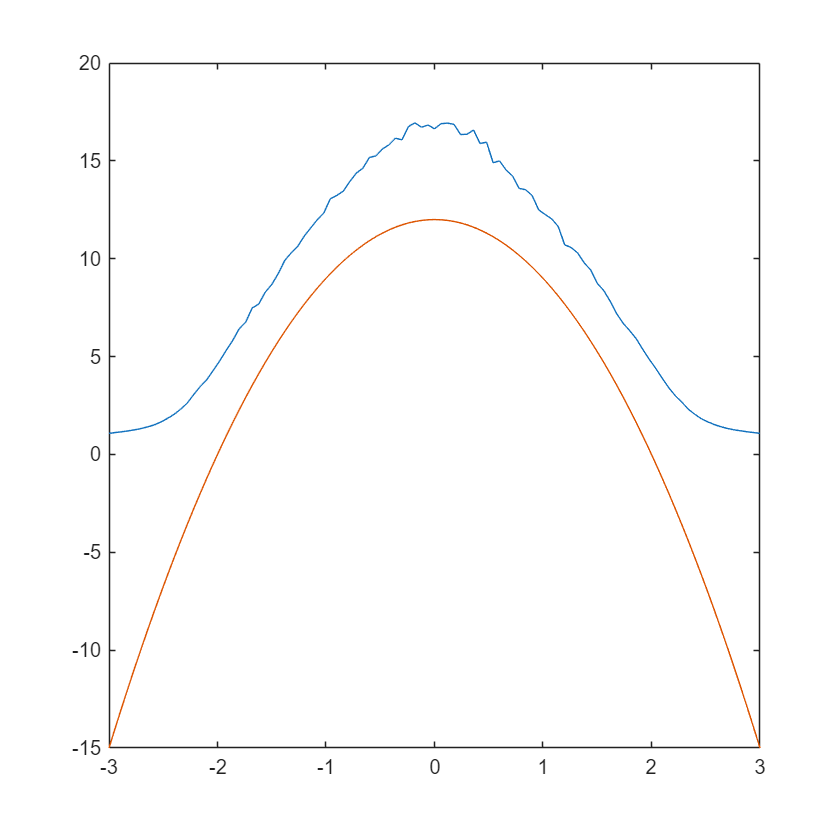


% plot(1:Central.N_col/Iteration_Re, -cumsum(C_n))
plot(Fermi_Energy, loc_length, Fermi_Energy, 12 * (4-Fermi_Energy.^2)/Disorder.^2)

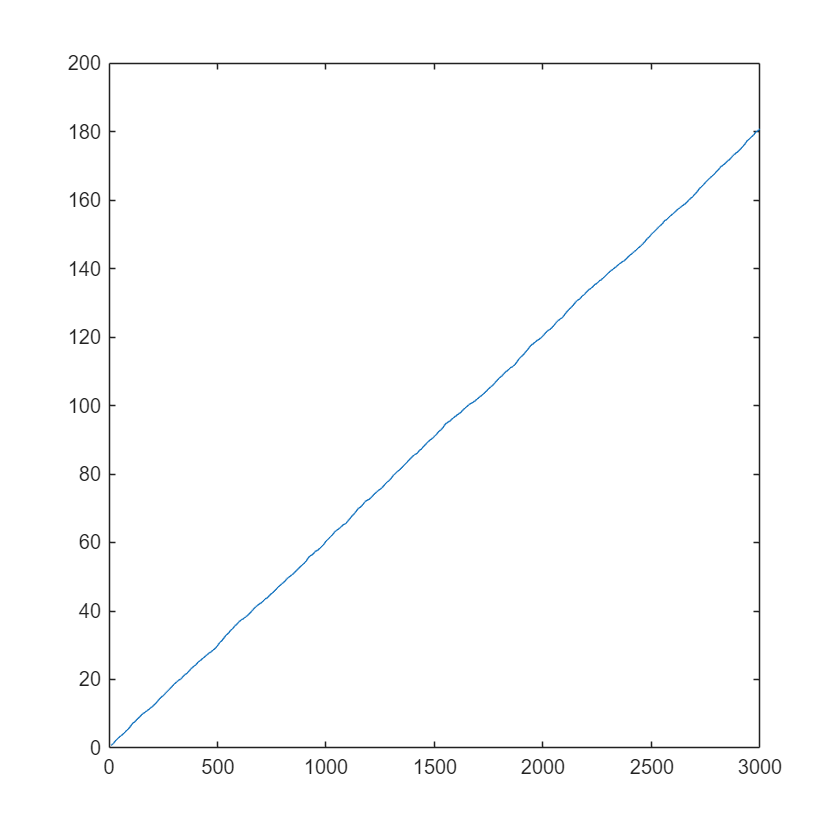

% disp(['\lambda_n = ',num2str(Central.N_col ./ sum(C_n,[],2))])
plot((1:Central.N_col/Iteration_Re)*Iteration_Re, cumsum(C_n(51,:)))


toc;

历时 809.362798 秒。


function [H_Metal, V_Metal] = Metal_2D_Hamiltonian(Lead, BoundaryCond)
% 端口哈密顿量
H_Metal = Lead.epsilon * eye(Lead.N_row) - Lead.t_y * diag(ones(Lead.N_row-1,1),-1) - Lead.t_y * diag(ones(Lead.N_row-1,1),+1);
% 端口周期性边界条件

if strcmp(BoundaryCond,"PBC")
    if Lead.N_row > 1
        H_Metal(1, Lead.N_row) = -Lead.t_y;
        H_Metal(Lead.N_row, 1) = -Lead.t_y;
    end
elseif strcmp(BoundaryCond,"OBC")

else
    error("Input must be 'PBC' or 'OBC' for periodic/open boundary condition");
end


% V_Lead 从端口向中心区的跃迁
V_Metal = - Lead.t_x * eye(Lead.N_row);
end


function [loc_length, C_n] = compute_loc_length(Length, H_CC, V_CC, Fermi_Energy, Disorder, Iteration_Re)

inv_V = pinv(V_CC);
C_n = zeros(Length/Iteration_Re,1);
Prod_n = eye(2*size(H_CC,1));

for ii = 1:Length
    T_n = [inv_V * (Fermi_Energy*eye(size(H_CC,1)) - H_CC - Disorder * diag(rand(size(H_CC,1),1)-0.5)), -inv_V * V_CC';
            eye(size(H_CC,1)), zeros(size(H_CC,1))];
    Prod_n = T_n * Prod_n;
    
    temp_Prod = zeros(size(T_n));
    R = zeros(size(T_n));
    if mod(ii,Iteration_Re) == 0
        b_n = zeros(size(Prod_n,1),1);
        % b_n(1) = norm(Prod_n(:,1));
        % temp_Prod(:, 1) = Prod_n(:,1) / b_n(1);
        % for jj = 2:size(Prod_n,2)
        %     v = Prod_n(:,jj);
        %     % proj_coeff = (Prod_n(:,1:jj-1)'*v) ./ vecnorm(Prod_n(:,1:jj-1))'.^2;
        %     proj_coeff = temp_Prod(:,1:jj-1)'*v;
        %     v = v -  (temp_Prod(:,1:jj-1) * proj_coeff);
        %     b_n(jj) = norm(v);
        %     temp_Prod(:, jj) = v / b_n(jj);
        % end
        
        for jj = 1:size(Prod_n,2)
            v = Prod_n(:,jj);
            for kk = 1:jj-1
                R(kk, jj) = temp_Prod(:, kk)' * v;
                v = v - R(kk, jj) * temp_Prod(:, kk);
            end
            R(jj, jj) = norm(v);
            b_n(jj) = norm(v);
            temp_Prod(:, jj) = v/R(jj, jj);
        end



        C_n(ii/Iteration_Re) = log(max(b_n));
        Prod_n = temp_Prod;
    end
end

loc_length = Length ./sum(C_n,1);
end